# Address double voting and explore vote consistency among 'experts'

% read in table and format it to our liking.

clsTab=jellyfish.readClassification.import_classification_file('170620');
%head(clsTab,5)
clsTab=jellyfish.readClassification.format_classification_table(clsTab);
%head(clsTab,5)
clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');

Classification info based on data downloaded on 8/6/20

Only classifications from the correct workflow are chosen and only from TNG50. 

The raw classification data is reformatted into a new table with columns contiaing the snapshot, id and host  Id for the object as well as the label (jelly or not):

%Classification data is reformatted into the following table (each line is a single classification instance):
%disp(clsTab(1:5,:))



% number of Inspectors
Inspectors=unique(clsTab.user_name);
%Inspectors=Inspectors.replace("-","_")

% number of objects
[idList, ia,ic]=unique(clsTab.subject_ids);

ngal=length(idList);

% create object table
objectTable=table(idList,clsTab.snap(ia),clsTab.subfind(ia),clsTab.host(ia),...
    'variableNames',{'subject_ids','snap','subfind','host'});

A table of objects is generated containing identifying information. To this we will add a classficiation column in the future:

disp(objectTable(1:5,:))

    subject_ids    snap    subfind    host
    ___________    ____    _______    ____

    3.6876e+07      33        2        0  
    3.6876e+07      33        3        0  
    3.6876e+07      33        4        0  
    3.6876e+07      33        5        0  
    3.6876e+07      33        6        0  



## Build classification tables for each inspectorin

We generate a table for each Inspector containing all objects, the number of times each object was classified and the total score - number of times it is classified as a JF. This classification table will be the input into a scoring function we use to tally the score according to whatever formula we choose. 

% initialize
%isJelly=false(size(idList));
%isJelly=zeros(size(idList));
%cnt=zeros(size(idList));

clear clsArray
clsArray.idList=idList;
for i=1:length(Inspectors)
    clsArray.(Inspectors(i)).cnt=zeros(size(idList));
    clsArray.(Inspectors(i)).score=zeros(size(idList));
    clsArray.(Inspectors(i)).isJelly=false(size(idList));
    
end

% populate classifications
for i=1:height(clsTab)
    uName=clsTab.user_name(i);
    indx=find(clsTab.subject_ids(i)==idList);
    
    clsArray.(uName).score(indx)=clsArray.(uName).score(indx)+...
        clsTab.isJelly(i);
    clsArray.(uName).cnt(indx)=clsArray.(uName).cnt(indx)+1;
    
end

for i=1:length(Inspectors)
    nObj(i)=sum(clsArray.(Inspectors(i)).cnt>0);
    clsArray.(Inspectors(i)).nObjects=sum(clsArray.(Inspectors(i)).cnt>0);
    clsArray.(Inspectors(i)).isJelly=clsArray.(Inspectors(i)).score>=1;
end

In the following we list the Inspectors according to no. of objects classified. For each we list the number of objects classified (also in percent). 

A table of the objects classified more than once is shown (if any). The table contains the object index, the number of times it was observed and its total score. If the score is non-zero and differs from the count then the Inspector has given different labels to the same object. 

If the Inspector has Inspected more than 99% but less than 100% of the objects we list which objects have not been observed.

Note: user  'sweetime' is Kiyun Yun.

% number of observed objects and minimal and maximal times voted, per
% Inspector

% sort Inspectors by no. of objects classified


[~,ix]=sort(nObj,'descend');

for i=ix
    fprintf('Inspector: %s \n', Inspectors(i))
    
    fprintf('No. of objects observed: %i, %4.2f %% \n',...
        sum(clsArray.(Inspectors(i)).cnt>0),sum(clsArray.(Inspectors(i)).cnt>0)/ngal*100)
    
    if sum(clsArray.(Inspectors(i)).cnt>1)>0
        inds=find(clsArray.(Inspectors(i)).cnt>1);
        fprintf('No. of objects observed more than once : %i \n',length(inds))
        
        
        tab=table(inds,clsArray.(Inspectors(i)).cnt(inds),clsArray.(Inspectors(i)).isJelly(inds),...
            'VariableNames',{'index';'count';'score'});
        
        head(tab,20)
        
    end
    
    if clsArray.(Inspectors(i)).nObjects/ngal>0.98 && clsArray.(Inspectors(i)).nObjects/ngal<0.9999
        fprintf('The indices of objects not observed are: \n')
        indxs=find(clsArray.(Inspectors(i)).cnt==0);
        objectTable(indxs,:)
    end
    
    fprintf('=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=\n')
    fprintf('\n')
    
end

Inspector: apillepich 


No. of objects observed: 3469, 100.00 % 


No. of objects observed more than once : 11 


ans = 11×3 table
    index    count    score
    _____    _____    _____

     416       3      false
     417       3      false
     418       3      false
     419       2      false
     420       2      false
     421       3      false
     422       2      false
     423       2      false
     424       3      false
     425       2      false
    1885       2      false


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: allisonmerritt 


No. of objects observed: 3467, 99.94 % 


The indices of objects not observed are: 


ans = 2×4 table
    subject_ids    snap     subfind      host
    ___________    ____    __________    ____

    3.6881e+07      50     2.9536e+05    172 
    3.7839e+07      67      4.771e+05    479 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: donnarim 


No. of objects observed: 3467, 99.94 % 


No. of objects observed more than once : 1 


ans = 1×3 table
    index    count    score
    _____    _____    _____

     362       2      false


The indices of objects not observed are: 


ans = 2×4 table
    subject_ids    snap     subfind      host
    ___________    ____    __________    ____

    3.6881e+07      50     2.9536e+05    172 
    3.7839e+07      67      4.771e+05    479 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: ezinger 


No. of objects observed: 3467, 99.94 % 


No. of objects observed more than once : 12 


ans = 12×3 table
    index    count    score
    _____    _____    _____

     416       7      false
     417       4      false
     418       6      false
     419       5      false
     420       6      false
     421       5      false
     422       5      false
     423       7      false
     424       6      false
     425       5      false
    2645       2      false
    3294       2      false


The indices of objects not observed are: 


ans = 2×4 table
    subject_ids    snap     subfind      host
    ___________    ____    __________    ____

    3.6881e+07      50     2.9536e+05    172 
    3.7839e+07      67      4.771e+05    479 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: gandhalij 


No. of objects observed: 3467, 99.94 % 


No. of objects observed more than once : 1 


ans = 1×3 table
    index    count    score
    _____    _____    _____

    1945       2      false


The indices of objects not observed are: 


ans = 2×4 table
    subject_ids    snap     subfind      host
    ___________    ____    __________    ____

    3.6881e+07      50     2.9536e+05    172 
    3.7839e+07      67      4.771e+05    479 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: sweetime 


No. of objects observed: 3467, 99.94 % 


No. of objects observed more than once : 20 


ans = 20×3 table
    index    count    score
    _____    _____    _____

      28       2      false
     148       2      false
     235       2      false
     284       2      false
     397       2      false
     416       2      false
     456       2      false
     552       2      false
     586       2      false
     636       2      false
     881       2      false
    1193       2      false
    1243       2      false
    1736       2      true 
    1751       2      false
    1796       2      false


The indices of objects not observed are: 


ans = 2×4 table
    subject_ids    snap     subfind      host
    ___________    ____    __________    ____

    3.6881e+07      50     2.9536e+05    172 
    3.7839e+07      67      4.771e+05    479 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: Dongwook 


No. of objects observed: 1818, 52.41 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: xkudsraw 


No. of objects observed: 269, 7.75 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: m_arcasedda 


No. of objects observed: 223, 6.43 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: sweetimetaiwan 


No. of objects observed: 149, 4.30 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: Young_Lo 


No. of objects observed: 77, 2.22 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: Paliliciun 


No. of objects observed: 35, 1.01 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


Inspector: Melina_t 


No. of objects observed: 1, 0.03 % 


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=


## Some conclusions :

- Only AP has observed all objects. All the rest have 'missed' 2 objects, though they have been given other objects multiple time. Interestingly - *They are the same 2 objects! *

- All of the objects observed multiple times by AP and EZ were consistently labeled non-JF. KY has observed 2 objects twice and has labeled them differently each time.

- There is one non-expert classifier, Dongwook, who has classified a significant number of objects: ~ 52% 

## compare classifications between experts

experts=Inspectors([5:9 11 1]);
exTag={'AM','AP','MD','EZ','GJ','KY', 'DW'};
clsmat=zeros(length(experts),length(experts));
clsmat2=clsmat;
for i=1:length(experts)
    clsmat(i,i)=clsArray.(experts(i)).nObjects;
    clsmat2(i,i)=clsArray.(experts(i)).nObjects;
    msk1=clsArray.(experts(i)).cnt>0;
    isJ1= clsArray.(experts(i)).isJelly;
    
    for j=i+1:length(experts)
        msk=clsArray.(experts(j)).cnt>0 & msk1; % look at objects both experts have classified
        
        % how consistent are the classifications
        isJ2= clsArray.(experts(j)).isJelly;
        clsmat(j,i)=round(sum(isJ1(msk)==isJ2(msk))/sum(msk)*100);
        clsmat(i,j)=clsmat(j,i);
        clsmat2(i,j)=sum(msk);
        %clsmat2(j,i)=sum(msk);
        
    end
end

%clsmat

We designate 6 'expert' Inspectors - the 5 Inspectors from Yun2019 (AP,KY,MD,GJ,EZ) and Allison Merrit (AM) . 

In the following table we show the consistency score between each pair of experts. The score is calculated over the objects classified by *both* Experts. The score consists of the number of identical classifications divided by the total number of objects classified by both, expressed as a percent ('What is the percentage of objects classified by both for which there is an agreement')

The diagonal of the table shows the number of objects classified by each Expert. For convenience the consistency score fro each Expert pairing is shown twice. 

tabb=table(clsmat(:,1),clsmat(:,2),clsmat(:,3),...
    clsmat(:,4),clsmat(:,5),clsmat(:,6),clsmat(:,7),...
    'VariableNames',exTag,'RowNames',exTag);
disp(tabb(1:6,1:6))

           AM      AP      MD      EZ      GJ      KY 
          ____    ____    ____    ____    ____    ____

    AM    3467      86      93      95      92      92
    AP      86    3469      86      87      89      89
    MD      93      86    3467      94      91      91
    EZ      95      87      94    3467      92      92
    GJ      92      89      91      92    3467      91
    KY      92      89      91      92      91    3467



In this following table we show the number of objects classified by both Experts in each pairing.

tabb2=table(clsmat2(:,1),clsmat2(:,2),clsmat2(:,3),...
    clsmat2(:,4),clsmat2(:,5),clsmat2(:,6),clsmat2(:,7),...
    'VariableNames',exTag,'RowNames',exTag);
disp(tabb2(1:6,1:6))

           AM      AP      MD      EZ      GJ      KY 
          ____    ____    ____    ____    ____    ____

    AM    3467    3467    3467    3467    3467    3467
    AP       0    3469    3467    3467    3467    3467
    MD       0       0    3467    3467    3467    3467
    EZ       0       0       0    3467    3467    3467
    GJ       0       0       0       0    3467    3467
    KY       0       0       0       0       0    3467



### Consistency conclusions: 

- All experts are consistent to >90%. The only exception is AP who is consistent to >86%. 

- AM, the 'new' expert, is consistent with other experts so there is no problem adding her on. 

Out of curiosity, I also add the consistency score of Dongwook (DW) the unknown classifier to the table for comparison: 

disp(tabb)

           AM      AP      MD      EZ      GJ      KY      DW 
          ____    ____    ____    ____    ____    ____    ____

    AM    3467      86      93      95      92      92      94
    AP      86    3469      86      87      89      89      86
    MD      93      86    3467      94      91      91      93
    EZ      95      87      94    3467      92      92      94
    GJ      92      89      91      92    3467      91      92
    KY      92      89      91      92      91    3467      92
    DW      94      86      93      94      92      92    1818



The consistency score for DW are similar to those between experts. I don't know who DW is and what their experience is, but if they are a complete novice this shows that the task of identifying JF is indeed something a layperson can do, and furthermore, that the instructions given in the project are sufficient to preform the task competently. 

## classification histograms

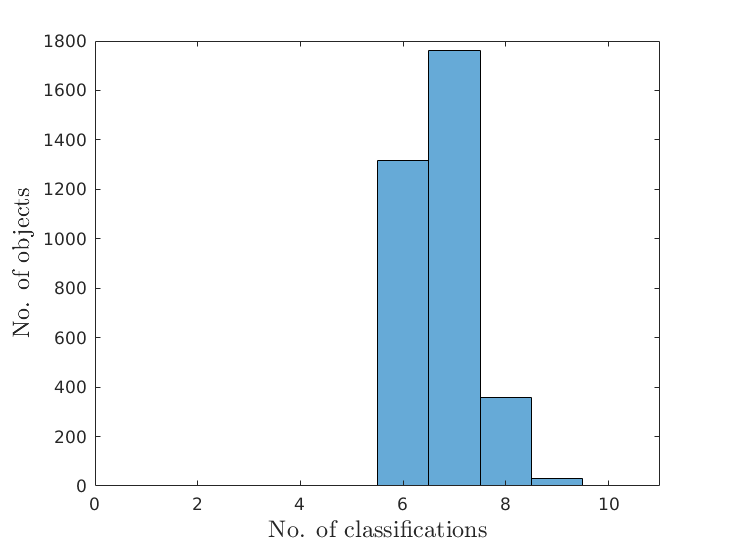

clsCount=zeros(size(idList));

for i=1:length(Inspectors)
    msk=clsArray.(Inspectors(i)).cnt>0;
    clsCount(msk)=clsCount(msk)+1;
end

hs=histogram(clsCount);
xlabelmine('No. of classifications');
ylabelmine('No. of objects');

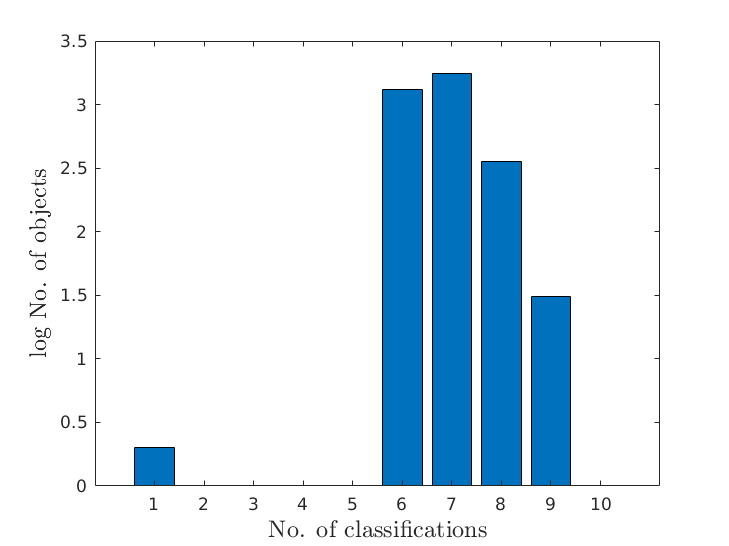


figure
bar(1:10,log10(hs.Values))
xlabelmine('No. of classifications');
ylabelmine('log No. of objects');

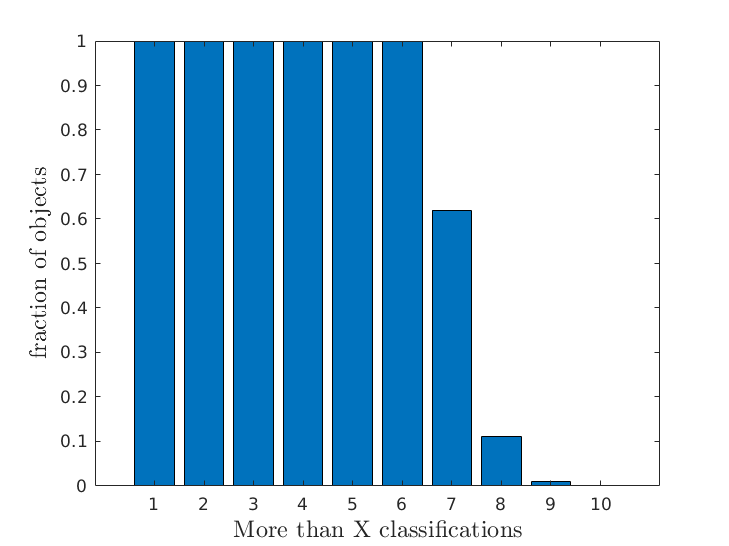

figure
bar(1:10,fliplr(cumsum(fliplr(hs.Values)))/ngal);
xlabelmine('More than X classifications');
ylabelmine('fraction of objects');

The same for experts

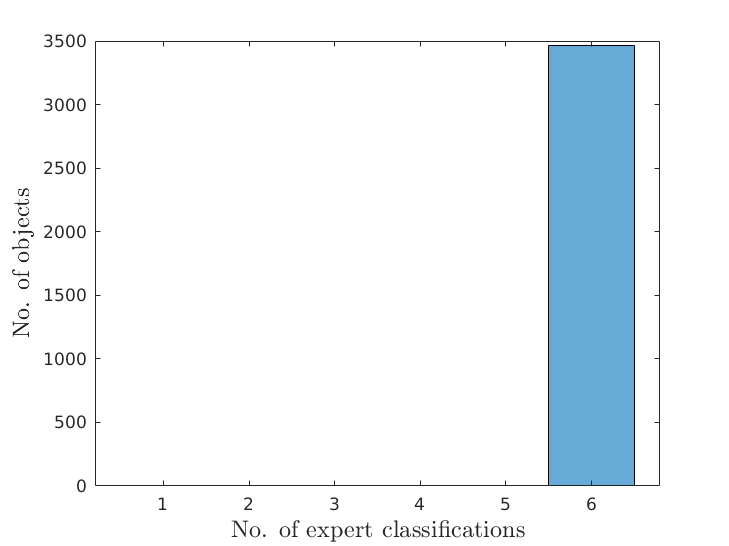


clsCount2=zeros(size(idList));

for i=1:length(experts)-1
    msk=clsArray.(experts(i)).cnt>0;
    clsCount2(msk)=clsCount2(msk)+1;
end

hs=histogram(clsCount2);
xlabelmine('No. of expert classifications');
ylabelmine('No. of objects');

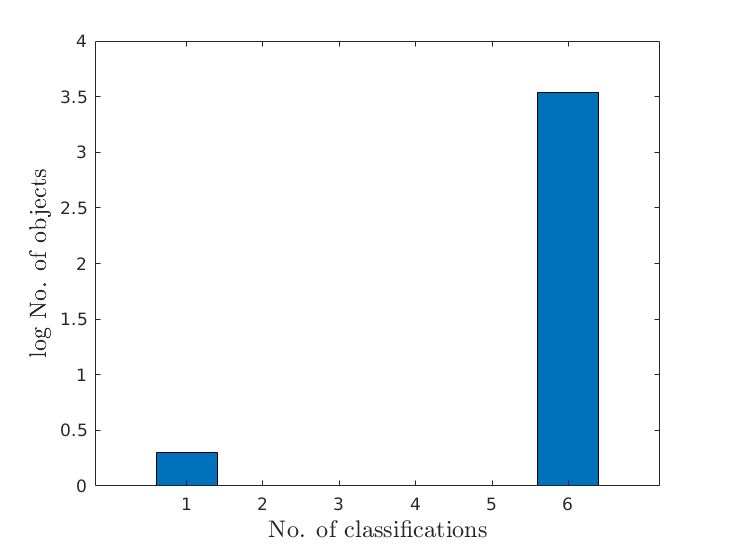


figure
bar(1:6,log10(hs.Values))
xlabelmine('No. of classifications');
ylabelmine('log No. of objects');

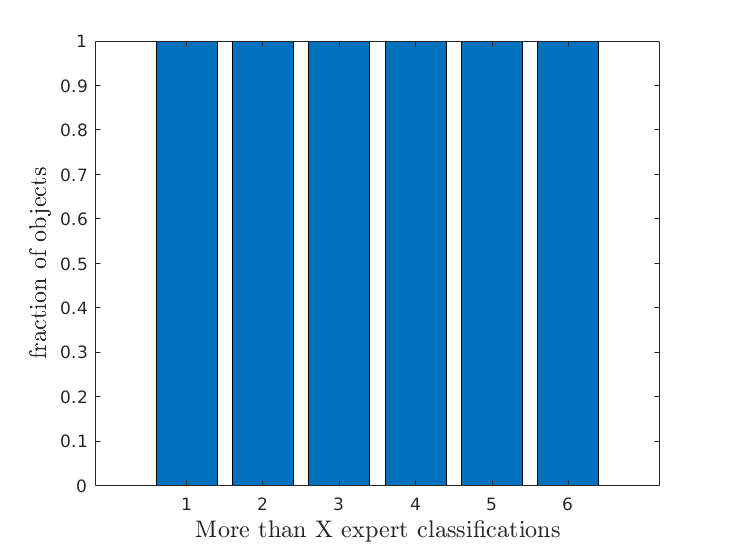


figure
bar(1:6,fliplr(cumsum(fliplr(hs.Values)))/ngal);
xlabelmine('More than X expert classifications');
ylabelmine('fraction of objects');